# XTD_A6: Interval Decoding Port Entry Decode D TransMat

% NOTE: This is written to run with PokeIn Alignment ONLY

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);

trlStrtWinDur = 3000;

pos2check = 1;

## Compile Data

trInt_DecTrlTransMat = cell(mlb.seqLength,mlb.seqLength);
trIntCON_DecTrlTransMat = cell(mlb.seqLength,mlb.seqLength);
trIntCON2_DecTrlTransMat = cell(mlb.seqLength,mlb.seqLength);

% Step through each animal's performance
for ani = 1:length(fileDirs)
    % Pull out temporary animal data
    curAni_TrialInfo_Pos = xtd_TrialInfo_POS{pos2check,ani};
    curAni_TrialInfo_All = xtd_TrialInfo_FULL{ani};
    curAni_SeqStarts = find([curAni_TrialInfo_All.Position]==1);
    curAni_TrialMask = mask_Trial{pos2check,ani};
    if strcmp(alignment{1}, 'PokeIn')
        curAni_IntMask = mask_PreInt{pos2check,ani};
        curAni_IntMaskCON = mask_PreIntCON{pos2check,ani};
    else
        curAni_IntMask = mask_PstInt{pos2check,ani};
        curAni_IntMaskCON =  mask_PstIntCON{pos2check,ani};
    end
    curAni_D = xtd_D(pos2check,:,ani);
%     curAni_D = xtd_HR(pos2check,:,ani);
    % Step through each trial
    for trl = 1:length(curAni_TrialInfo_Pos)
        % Identify the sequence the 4 comes from
        curSeqStart = curAni_SeqStarts(find(curAni_SeqStarts<=curAni_TrialInfo_Pos(trl).TrialNum,1,'last'));
        curSeqVect = [curAni_TrialInfo_All(curSeqStart:curAni_TrialInfo_Pos(trl).TrialNum).Odor];
        osLog = mod(curSeqVect,10)~=1:pos2check;
        if sum(osLog)==0
            osPos = pos2check;
            osOdr = pos2check;
        else
            osPos = find(osLog);
            osOdr = mod(curSeqVect(osPos),10);
        end
        % Create a trial start window mask
        curTrlStrtNdx = find(curAni_TrialMask(:,trl),1,'first');
        replayMask = false(size(mlb.obsvTimeVect));
        replayMask(curTrlStrtNdx-(trlStrtWinDur/2/mlb.dsRate):curTrlStrtNdx+((trlStrtWinDur/2/mlb.dsRate)-1)) = true;
        tempReplay = nan(sum(replayMask),mlb.seqLength);
        tempReplay_CON = nan(sum(replayMask),mlb.seqLength);
        tempReplay_CON2 = nan(sum(replayMask),mlb.seqLength);
        if strcmp(alignment{1}, 'PokeIn')
            curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'first');
        else
            curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last');
        end
        for pos = 1:mlb.seqLength
            tempReplay(:,pos) = mean(curAni_D{pos}(replayMask, curAni_IntMask(:,trl),trl),2,'omitnan');
            tempReplay_CON(:,pos) = mean(curAni_D{pos}(replayMask, curAni_IntMaskCON(:,trl),trl),2,'omitnan');
            tempReplay_CON2(:,pos) = curAni_D{pos}(replayMask, curAni_IntMaskCON2,trl);
        end
        trInt_DecTrlTransMat{osOdr,osPos} = cat(3,trInt_DecTrlTransMat{osOdr,osPos}, tempReplay);
        trIntCON_DecTrlTransMat{osOdr,osPos} = cat(3,trIntCON_DecTrlTransMat{osOdr,osPos}, tempReplay_CON);
        trIntCON2_DecTrlTransMat{osOdr,osPos} = cat(3,trIntCON2_DecTrlTransMat{osOdr,osPos}, tempReplay_CON2);
    end
end


## Plot Things :fingerscrossed:

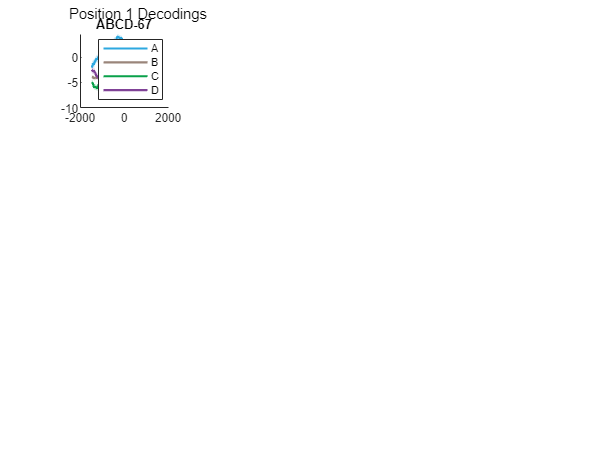

windowXticks = (trlStrtWinDur/2*-1:mlb.dsRate:(trlStrtWinDur/2-mlb.dsRate)) + mlb.dsRate/2;

figure;
curTrInt = trInt_DecTrlTransMat;
% curTrInt = trIntCON_DecTrlTransMat;
% curTrInt = trIntCON2_DecTrlTransMat;
spNdxs = reshape(1:numel(trInt_DecTrlTransMat), [mlb.seqLength, mlb.seqLength])';
for osT = 1:numel(trInt_DecTrlTransMat)
    if isempty(trInt_DecTrlTransMat{osT})
        continue;
    else
        subplot(mlb.seqLength, mlb.seqLength, spNdxs(osT));
        p = nan(1,mlb.seqLength);
        for pos = 1:mlb.seqLength
            p(pos) = mlb.PlotMeanVarLine(windowXticks,curTrInt{osT}(:,pos,:),3,0,mlb.PositionColors(pos,:));
        end
        seqID = [mlb.Rosetta{1:mlb.seqLength}];
        [osO,osP] = ind2sub([mlb.seqLength, mlb.seqLength], osT);
        seqID(osP) = mlb.Rosetta{osO};
        title(sprintf('%s-%i',seqID,size(curTrInt{osT},3)));
%         set(gca, 'ylim', [0 1]);
    end
end
legend(p,mlb.Rosetta(1:mlb.seqLength));
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
    'String', sprintf('Position %i Decodings',pos2check),...
    'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');